%scene_data_train = 'site_mfccs/s2lam029_190520/s2lam029_190520_2019-05-20_11-30'
%scene_data_test = 'site_mfccs/s2lam029_190520/s2lam029_190520_2019-05-20_11-40'
scene_data_train = 'site_mfccs/s2lam026_190421/s2lam026_190421_2019-04-21_12-00/'

scene_data_train = 'site_mfccs/s2lam026_190421/s2lam026_190421_2019-04-21_12-00/'

scene_data_test = 'site_mfccs/s2lam026_190421/s2lam026_190421_2019-04-21_12-10/'

scene_data_test = 'site_mfccs/s2lam026_190421/s2lam026_190421_2019-04-21_12-10/'

imdsTrain = imageDatastore(scene_data_train, ...
    'IncludeSubfolders',true,'LabelSource','foldernames')

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\site_mfccs\s2lam026_190421\s2lam026_190421_2019-04-21_12-00\0.png';
                              ' ...\site_mfccs\s2lam026_190421\s2lam026_190421_2019-04-21_12-00\1.png';
                              ' ...\site_mfccs\s2lam026_190421\s2lam026_190421_2019-04-21_12-00\10.png'
                               ... and 41 more
                              }
                     Folders: {
                              ' ...\site_mfccs\s2lam026_190421\s2lam026_190421_2019-04-21_12-00'
                              }
                      Labels: [s2lam026_190421_2019-04-21_12-00; s2lam026_190421_2019-04-21_12-00; s2lam026_190421_2019-04-21_12-00 ... and 41 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jp

imdsTest = imageDatastore(scene_data_test, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

labelTable = countEachLabel(imdsTest)

labelTable = 1×2 table
                 Label                  Count
    ________________________________    _____

    s2lam026_190421_2019-04-21_12-10     41  


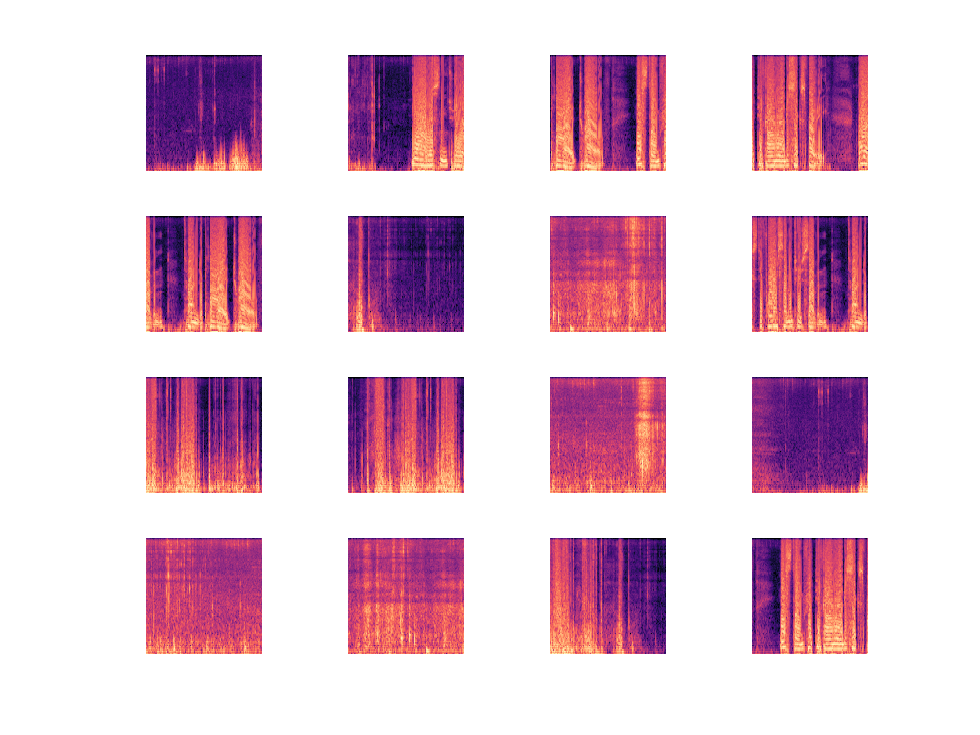


numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end


net = vggish

net =   SeriesNetwork with properties:

         Layers: [24×1 nnet.cnn.layer.Layer]
     InputNames: {'InputBatch'}
    OutputNames: {'regressionoutput'}


%analyzeNetwork(net)
inputSize = net.Layers(1).InputSize

inputSize =     96    64     1


augimdsTrain= augmentedImageDatastore(inputSize(1:3),imdsTrain,"ColorPreprocessing","rgb2gray");
augimdsTest = augmentedImageDatastore(inputSize(1:3),imdsTest,"ColorPreprocessing","rgb2gray")

augimdsTest =   augmentedImageDatastore with properties:

             NumObservations: 41
                       Files: {41×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'rgb2gray'
                  OutputSize: [96 64]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


YPred = predict(net,augimdsTest)

YPred = 41×128 single matrix
         0         0    2.8583         0         0         0    0.7934         0         0         0         0         0         0         0         0   11.1326         0         0         0         0         0         0         0         0         0    7.5684         0         0    0.1697         0    2.1247         0    4.7784         0    7.2307         0         0         0         0         0    7.4144         0    4.9117         0    1.9744         0         0         0    0.2479         0
         0         0    2.4605         0         0         0    1.3413         0         0         0         0         0         0         0         0    8.6819         0         0         0         0         0         0         0         0         0    5.4097         0         0    2.2291         0    2.0658         0    3.1014         0    4.3030         0         0         0         0         0    5.2359         0    5.2417         0    1.5604         0         0

[numFrames, numFeatures] = size(YPred)

numFrames = 41

numFeatures = 128